#  ECG grand average

Stimulus-locked grand average. For each trial, a baseline was created by averaging physiological time-series data from 3 seconds before the thermal stimulation onset.  A stimulus-locked physiological response was generated by subtracting the baseline value from the data in the 20-second period after the stimulation onset. 

clear;
close all;

basedir = '/Users/clinpsywoo/github/CRB_project/MWW_inprep/scripts';
cd(basedir);

load('../data/CRB_dataset_ECG_lpf1Hz_DS25Hz_021916.mat');
% load('../data/CRB_dataset_ECG_lpf5Hz_DS25Hz_120516.mat');

figdir = '../figures';

for j = [1:38 40:numel(D.Continuous.data)] % 39th subj: missing data 
    
    scr = D.Continuous.data{j};
    
    ons = D.Event_Level.data{j}(:,5);
    
    for ii = 1:6
        for jj = 1:3
            signal{j}.cond{ii, jj} = [];
        end
    end
        
    for i = 1:numel(ons)
        
        temp_lev = D.Event_Level.data{j}(i,11)-43;
        reg_lev = D.Event_Level.data{j}(i,16)+2;
        a = round((ons(i)-3)*25);
        signal{j}.cond{temp_lev, reg_lev}(end+1,:) = scr(a:(a+(23*25))); 
    end
    
end


clear signal_m;
for i = 1:6
    for j = 1:3
        kk = 0;
        for subj = [1:38 40:numel(signal)]
            kk = kk + 1;
            signal_m{i,j}(kk,:) = mean(signal{subj}.cond{i,j} - repmat(mean(signal{subj}.cond{i,j}(:,1:75),2), 1, size(signal{subj}.cond{i,j},2)));
                                                     % subtracting the baseline, and then average
        end
    end
end


## All temperature; ECG

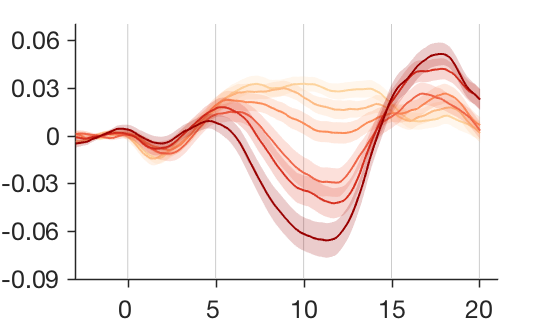

close all;

x = 1:576;
create_figure('shading');
cols = [0.9922    0.8314    0.6196
    0.9922    0.7333    0.5176
    0.9882    0.5529    0.3490
    0.9373    0.3961    0.2824
    0.8431    0.1882    0.1216
    0.6000         0         0];

for i = (3:5:24)*25
    line([i i], [-.09 .07], 'col', [.8 .8 .8], 'linewidth', 1);
end

for i = 1:6
    hold on;
    wani_plot_shading(x, mean(cat(1,signal_m{i,:})), ste(cat(1,signal_m{i,:})), 'color', cols(i,:), 'alpha', .2);
    % wani_plot_shading(x, mean(cat(1,signal_m{i,:})), repmat(wsbar(cat(1,signal_m{i,:})), 1, size(cat(1,signal_m{i,:}),2)), 'color', cols(i,:), 'alpha', .2);
    % plot(x, mean(cat(1,signal_m{i,:})), 'color', cols(i,:), 'linewidth', 2);
end

set(gcf, 'position', [50   126   549   324]);
set(gca, 'ylim',  [-.09 .07], 'linewidth', 1.5, 'TickDir', 'out', 'TickLength', [.02 .02], 'Xtick', (3:5:24)*25, 'ytick', -.09:.03:.1);
set(gca, 'XTickLabel', get(gca, 'XTick')./25-3);
set(gca, 'fontSize', 25);


savename = fullfile(figdir, 'Temp_all_ECG_grandavg_full.pdf');

pagesetup(gcf);
saveas(gcf, savename);

pagesetup(gcf);
saveas(gcf, savename)


## stat test

yy_max_temp = cellfun(@(x) min(x')', signal_m, 'Uniformoutput', false);
% yy_max_temp = cellfun(@(x) min(x(:,200:576)')', signal_m, 'Uniformoutput', false);

temp = repmat(1:6, 1, 3)';
reg = [ones(6,1)*-1; zeros(6,1); ones(6,1)*1];
for i = 1:numel(yy_max_temp{1})
    xx{i} = [temp reg scale(temp,1).*scale(reg,1)];

    k = 0;
    for j = 1:3
        for jj = 1:6
            k = k + 1;
            yy_max{i}(k,1) = yy_max_temp{jj,j}(i);
        end
    end
end

glm_ecg_max = glmfit_multilevel(yy_max, xx, [], 'names', {'intcp', 'temp', 'reg', 'intera'}, ...
    'weighted', 'verbose', 'boot', 'nresample', 10000);

Analysis description: Second Level of Multilevel Model  
GLS analysis

Observations:  41, Predictors:   1
Outcome names: intcp	temp	reg	intera	
Weighting option: weighted
Inference option: bootstrap

Other Options:
	Plots: No
	Robust: no
	Save: No
	Output file: glmfit_general_output.txt
	R & B - type Empirical Bayes reweighting.
 Min p-value is 0.000000. Needed: 10000 samples
 Bootstrapping 10000 samples... Bootstrap done in 0.00 s, bias correct in 0.00 s 
Total time: 0.45 s

________________________________________
Average p-value tolerance (average max alpha): 0.0060

Bootstrapped statistics. Bootstrap inference
	Outcome variables:
	intcp	temp	reg	intera	
Adj. mean	-0.04	-0.01	-0.00	-0.00	

2nd-level B01
	intcp	temp	reg	intera	
Coeff	-0.04	-0.01	-0.00	-0.00	
STE	0.00	0.00	0.00	0.00	
t	-6.98	-3.24	-0.83	-0.92	
Z	-3.54	-3.05	-0.60	-0.85	
p	0.0002	0.0011	0.2748	0.1963	

________________________________________


yy_sum_temp = cellfun(@(x) sum(x,2), signal_m, 'Uniformoutput', false);

temp = repmat(1:6, 1, 3)';
reg = [ones(6,1)*-1; zeros(6,1); ones(6,1)*1];
for i = 1:numel(yy_sum_temp{1})
    xx{i} = [temp reg scale(temp,1).*scale(reg,1)];

    k = 0;
    for j = 1:3
        for jj = 1:6
            k = k + 1;
            yy_sum{i}(k,1) = yy_sum_temp{jj,j}(i);
        end
    end
end

glm_ecg_sum = glmfit_multilevel(yy_sum, xx, [], 'names', {'intcp', 'temp', 'reg', 'intera'}, ...
    'weighted', 'verbose', 'boot', 'nresample', 10000);

Analysis description: Second Level of Multilevel Model  
GLS analysis

Observations:  41, Predictors:   1
Outcome names: intcp	temp	reg	intera	
Weighting option: weighted
Inference option: bootstrap

Other Options:
	Plots: No
	Robust: no
	Save: No
	Output file: glmfit_general_output.txt
	R & B - type Empirical Bayes reweighting.
 Min p-value is 0.000483. Needed: 10000 samples
 Bootstrapping 10000 samples... Bootstrap done in 0.00 s, bias correct in 0.00 s 
Total time: 0.53 s

________________________________________
Average p-value tolerance (average max alpha): 0.0060

Bootstrapped statistics. Bootstrap inference
	Outcome variables:
	intcp	temp	reg	intera	
Adj. mean	8.45	-1.87	-1.84	-0.28	

2nd-level B01
	intcp	temp	reg	intera	
Coeff	8.49	-1.88	-1.86	-0.29	
STE	2.05	0.67	0.77	0.56	
t	3.81	-2.56	-2.28	-0.56	
Z	3.68	-2.40	-2.04	-0.32	
p	0.0001	0.0083	0.0207	0.6267	

________________________________________


## plot: max

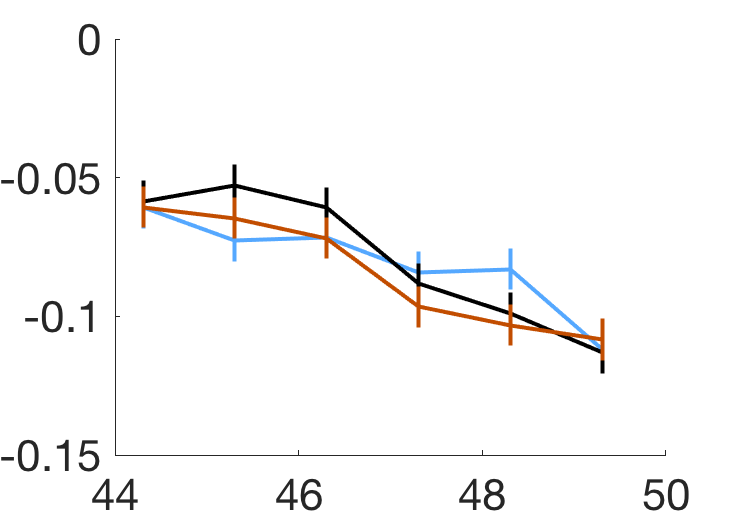


reg_all{1} = cat(2,yy_max_temp{:,1})';
reg_all{2} = cat(2,yy_max_temp{:,2})';
reg_all{3} = cat(2,yy_max_temp{:,3})';

x = 44.3:1:49.3;
y = [mean(reg_all{1},2) mean(reg_all{2},2) mean(reg_all{3},2)];
% se = [repmat(wsbar(reg_all{1}'), 6, 1) repmat(wsbar(reg_all{2}'), 6, 1) repmat(wsbar(reg_all{3}'), 6, 1)];
se = repmat(barplot_get_within_ste([reg_all{1}; reg_all{2}; reg_all{3}]'), 6, 3);


create_figure('plot');
set(gcf, 'position', [360   438   368   260]);

col = [0.3333    0.6588    1.0000
       0         0         0
       0.7608    0.3020    0];

for i = 1:3
    hold on;
    h = errorbar(x, y(:,i), se(:,i), 'color', col(i,:), 'linewidth', 2); %, 'markersize', 4, 'markerfacecolor', col(i,:));
    h.CapSize = 0;
end
 
% set(gca, 'xlim', [43.8 49.8], 'linewidth', 2, 'xtick', 44:49, 'tickdir',...
%     'out', 'ticklength', [.02 .02], 'ytick', 0:.2:1.2, 'ylim',[0 1.3]);

set(gca, 'fontsize', 22);

## plot: sum

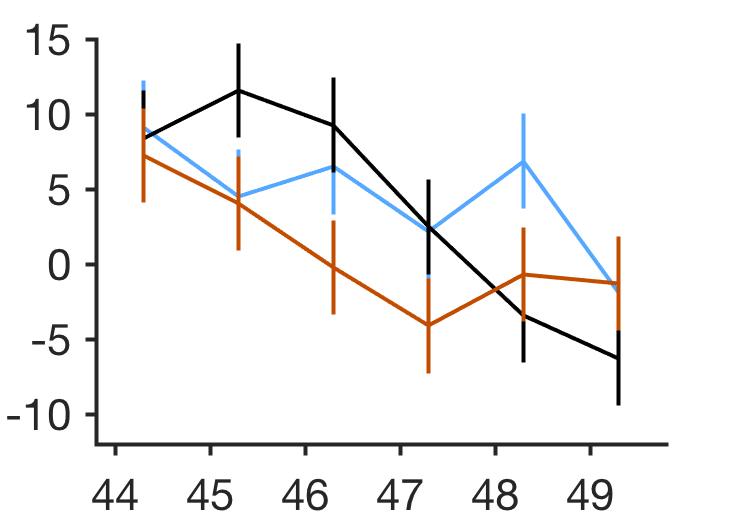


reg_all{1} = cat(2,yy_sum_temp{:,1})';
reg_all{2} = cat(2,yy_sum_temp{:,2})';
reg_all{3} = cat(2,yy_sum_temp{:,3})';

x = 44.3:1:49.3;
y = [mean(reg_all{1},2) mean(reg_all{2},2) mean(reg_all{3},2)];
% se = [repmat(wsbar(reg_all{1}'), 6, 1) repmat(wsbar(reg_all{2}'), 6, 1) repmat(wsbar(reg_all{3}'), 6, 1)];
se = repmat(barplot_get_within_ste([reg_all{1}; reg_all{2}; reg_all{3}]'), 6, 3);


create_figure('plot');
set(gcf, 'position', [360   438   368   260]);

col = [0.3333    0.6588    1.0000
       0         0         0
       0.7608    0.3020    0];

for i = 1:3
    hold on;
    h = errorbar(x, y(:,i), se(:,i), 'color', col(i,:), 'linewidth', 2); %, 'markersize', 4, 'markerfacecolor', col(i,:));
    h.CapSize = 0;
end

set(gca, 'xlim', [43.8 49.8], 'linewidth', 2, 'xtick', 44:49, 'tickdir',...
    'out', 'ticklength', [.02 .02], 'ytick', -10:5:15, 'ylim',[-12 15]);

set(gca, 'fontsize', 22);


% %figdir = '/Users/clinpsywoo/Dropbox (CANLAB)/c_crb_analysis/analysis/figure';
% savename = fullfile(figdir, 'test_scr_int.pdf');
% pagesetup(gcf);
% saveas(gcf, savename);
% 
% pagesetup(gcf);
% saveas(gcf, savename);


